# Cluster

## Accès dossier et choix essai

Il est nécessaire d'avoir lancé "Correlation.mat" précédement

clear;
Type = "C6C0SN";
Materiau = "3135";
Eprouvette ='1';
Numero = '3';
 
addpath('/home/tdelaselle/Documents/Codes/Codes-matlab/Fonctions');
repertoire_traitees = acces_donnees_traitees();
addpath(strcat(repertoire_traitees,'/',Type,'/',Materiau));
Naming = strcat(Type,'_',Materiau,'_',Eprouvette,'.',Numero);
load(strcat(Naming,'.mat'));
WF = TimeT(WF);

## Sélection WF pour clusters

 ;
Channel = 6;
seuil =0.96;
Nbre = 10;

HDD = sortrows(HDD,'Time'); 


###         Statistiques de corrélation : 

if pretrig == 0
    "Pré-trigger inclu"
else
    "Pré-trigger exclu"
end

ans = "Pré-trigger inclu"

strcat("Taille de la fenêtre de corrélation : ",string(impul))

ans = "Taille de la fenêtre de corrélation : 300"

% Calcul taux de corrélation moyen 
moy1 = 0;
moy2 = 0;
moy3 = 0;
moy4 = 0;
moy5 = 0;
moy6 = 0;


if exist('Cor1','var')
    for i = 1:length(Cor1)-1
       moy1 = moy1+sum(Cor1(i,(i+1):end));
    end
    moy1 = 2*moy1/(length(Cor1)-1)^2;
    Nbre1 = length(find(Cor1(:,:)>=seuil));
else
    moy1 = 0;
    Nbre1 = 0;
end


for i = 1:length(Cor2)-1
    moy2 = moy2+sum(Cor2(i,(i+1):end));
end
moy2 = 2*moy2/(length(Cor2)-1)^2;
Nbre2 = length(find(Cor2(:,:)>=seuil));
Statistiques = table([1;2],[moy1;moy2],[Nbre1;Nbre2],'VariableNames',{'Channel', 'Taux de corrélation moyen', 'Nombre de corrélation dépassant le seuil'});
if exist('Cor3','var')
    for i = 1:length(Cor3)-1
        moy3 = moy3+sum(Cor3(i,(i+1):end));
    end
    moy3 = 2*moy3/(length(Cor3)-1)^2;
    Nbre3 = length(find(Cor3(:,:)>=seuil));
    Statistiques = table([1;2;3],[moy1;moy2;moy3],[Nbre1;Nbre2;Nbre3],'VariableNames',{'Channel', 'Taux de corrélation moyen', 'Nombre de corrélation dépassant le seuil'});
end
if exist('Cor4','var')
    for i = 1:length(Cor4)-1
        moy4 = moy4+sum(Cor4(i,(i+1):end));
    end
    moy4 = 2*moy4/(length(Cor4)-1)^2;
    Nbre4 = length(find(Cor4(:,:)>=seuil));
    Statistiques = table([1;2;3;4],[moy1;moy2;moy3;moy4],[Nbre1;Nbre2;Nbre3;Nbre4],'VariableNames',{'Channel', 'Taux de corrélation moyen', 'Nombre de corrélation dépassant le seuil'});
end
if exist('Cor5','var')
    for i = 1:length(Cor5)-1
        moy5 = moy5+sum(Cor5(i,(i+1):end));
    end
    moy5 = 2*moy5/(length(Cor5)-1)^2;
    Nbre5 = length(find(Cor5(:,:)>=seuil));
    Statistiques = table([1;2;3;4;5],[moy1;moy2;moy3;moy4;moy5],[Nbre1;Nbre2;Nbre3;Nbre4;Nbre5],'VariableNames',{'Channel', 'Taux de corrélation moyen', 'Nombre de corrélation dépassant le seuil'});
end
if exist('Cor6','var')
    for i = 1:length(Cor6)-1
        moy6 = moy6+sum(Cor6(i,(i+1):end));
    end
    moy6 = 2*moy6/(length(Cor6)-1)^2;
    Nbre6 = length(find(Cor6(:,:)>=seuil));
    Statistiques = table([1;2;3;4;5;6],[moy1;moy2;moy3;moy4;moy5;moy6],[Nbre1;Nbre2;Nbre3;Nbre4;Nbre5;Nbre6],'VariableNames',{'Channel', 'Taux de corrélation moyen', 'Nombre de corrélation dépassant le seuil'});
end
Statistiques

Statistiques = 6×3 table
    Channel    Taux de corrélation moyen    Nombre de corrélation dépassant le seuil
    _______    _________________________    ________________________________________

       1                      0                                  0                  
       2                0.58834                              24414                  
       3                0.46327                                915                  
       4                0.52429                               8839                  
       5                0.73547                                 21                  
       6                0.54561                              10261                  


###         Extraction des WF et constitution des clusters : 

% % Comptage du nombre de waveforms par channel
% po = HDD.CH;
% chNbre = zeros(6,1);
% chNbre(1) = length(find(po==1));   
% chNbre(2) = length(find(po==2));
% chNbre(3) = length(find(po==3));
% chNbre(4) = length(find(po==4));
% chNbre(5) = length(find(po==5));
% chNbre(6) = length(find(po==6));
chNbre = Nch(HDD);

if Channel == 1
    Multi = extraction(chNbre(1),Cor1,Nbre,seuil);
elseif Channel == 2
    Multi = extraction(chNbre(2),Cor2,Nbre,seuil);
elseif Channel == 3
    Multi = extraction(chNbre(3),Cor3,Nbre,seuil);
elseif Channel == 4
    Multi = extraction(chNbre(4),Cor4,Nbre,seuil);
elseif Channel == 5
    Multi = extraction(chNbre(5),Cor5,Nbre,seuil);
elseif Channel == 6
    Multi = extraction(chNbre(6),Cor6,Nbre,seuil);
end

% Tri des clusters par nombre décroissant de WF
A1 = {Multi ; cell(1,length(Multi))}';
for i = 1:length(Multi)
    A1{i,1} = Multi{i};
    A1{i,2} = length(Multi{i});
end
A1 = sortrows(A1,2,'descend');
Multi = {A1{:,1}};

% Calculs et affichage de stat des clusters du ch choisi
len1 = size(Multi);
M1 = table('Size',[len1(2) 5],'VariableTypes',["double","double","double","double","double"],'VariableNames',{'Nombre_WF','Charge_moyenne','Ecart_type_charge','Nombre_cycles','ecart_type_cycle'});

for i = 1:len1(2)
    l = length(Multi{i});
    Charge = zeros(1,l);
    Num_cycles = zeros(1,l);
    % Constitution listes de charge et cycle correspondant à chaque WF d'un multi
    for j = 1:l
        idx = find(HDD.HDDWF==strcat(string(Channel),'_',string(Multi{i}(j))));
        Charge(j) = HDD.PARA1(idx);
        Num_cycles(j) = fix(HDD.CYCLES(idx));
    end
    % Calculs moyennes et écarts types sur ces listes, remplissage table
    M1.Nombre_WF(i) = l;
    M1.Charge_moyenne(i) = mean(Charge);
    M1.Ecart_type_charge(i) = std(Charge);
    M1.Nombre_cycles(i) = max(Num_cycles)-min(Num_cycles);
    Num_cycles = Num_cycles(2:end)-Num_cycles(1:(end-1));
    M1.ecart_type_cycle(i) = std(Num_cycles);
end

Statistiques_clusters_channel = M1

Statistiques_clusters_channel = 5×5 table
    Nombre_WF    Charge_moyenne    Ecart_type_charge    Nombre_cycles    ecart_type_cycle
    _________    ______________    _________________    _____________    ________________

       300           4163.4             818.66                0                 0        
        82           1455.4              640.4                0                 0        
        25           1227.2             733.38                0                 0        
        25            462.8             251.36                0                 0        
        10           1677.5             628.53                0                 0        


## Contraintes au sein d'un cluster

 ;

Choix des variables :

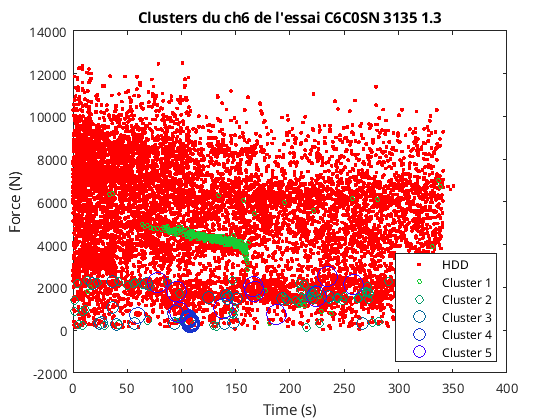

ParaX = "Time";
ParaY = "PARA1";

figure();
plot(HDD.(ParaX),HDD.(ParaY),'r.','DisplayName','HDD');
hold on   
xlabel(HDD.Properties.VariableDescriptions{ParaX});
ylabel(HDD.Properties.VariableDescriptions{ParaY});
labels = {'HDD'};
legend(labels,"Location","southeast");
len1 = size(Multi); 
for i = 1:len1(2)
    l = size(Multi{i});
    plot(HDD.(ParaX)(HDD.HDDWF==strcat(string(Channel),'_',string(Multi{i}(1)))),HDD.(ParaY)(HDD.HDDWF==strcat(string(Channel),'_',string(Multi{i}(1)))),'o',"MarkerSize",i*3,"Color",[(0.5-i*1/(len1(2)))^2 (1-i*1/len1(2)) i*1/len1(2)],'DisplayName',strcat('Cluster'," ",string(i)));
    for j = 2:l(2)
        h = plot(HDD.(ParaX)(HDD.HDDWF==strcat(string(Channel),'_',string(Multi{i}(j)))),HDD.(ParaY)(HDD.HDDWF==strcat(string(Channel),'_',string(Multi{i}(j)))),'o',"MarkerSize",i*3,"Color",[(0.5-i*1/(len1(2)))^2 (1-i*1/len1(2)) i*1/len1(2)]);
        h.Annotation.LegendInformation.IconDisplayStyle = 'off';
    end
end
title(strcat("Clusters du ch",string(Channel)," de l'essai ",Type," ",Materiau," ",Eprouvette,'.',Numero));
hold off

% Partie affichage de la position cyclique 
dte = mean(Cycle(2:end,2)-Cycle(1:(end-1),2));

The end operator must be used within an array index expression.

[x0, maxi, mini] = depart_cycle(TDD,1/dte);
% maxi = maxi*1e3;
% mini = mini*1e3;

moy = (maxi+mini)/2;
Dcharge = maxi-moy;
x = (0:0.01:1);
c = [mini maxi];
figure();
hold on; 
plot(x,Dcharge*sin(2*pi*x+6*pi/4)+moy);
plot([0 1],[moy moy],'r--');
ylabel('Charge (N)');
xlabel("Cycle de fatigue normalisé");
title(strcat("Cycles des WF des clusters du ch",string(Channel),", essai ",Type," ",Materiau," ",Eprouvette,'.',Numero));
labels = {'Cycle de fatigue',"Limite charge moy"};
legend(labels,"Location","south");
plot(HDD.CYCLES-fix(HDD.CYCLES),HDD.PARA1,'r.','DisplayName','HDD');
len1 = size(Multi); 
for i = 1:len1(2)
    l = size(Multi{i});
    Cy = (HDD.CYCLES(HDD.HDDWF==strcat(string(Channel),'_',string(Multi{i}(1)))))-fix(HDD.CYCLES(HDD.HDDWF==strcat(string(Channel),'_',string(Multi{i}(1)))));
    plot(Cy,HDD.PARA1(HDD.HDDWF==strcat(string(Channel),'_',string(Multi{i}(1)))),'.',"MarkerSize",(i*5),"MarkerEdgeColor",[(0.5-i*1/(len1(2)))^2 (1-i*1/len1(2)) i*1/len1(2)],'DisplayName',strcat('Cluster'," ",string(i)));
    for j = l(2):-1:1
        Cy = (HDD.CYCLES(HDD.HDDWF==strcat(string(Channel),'_',string(Multi{i}(j)))))-fix(HDD.CYCLES(HDD.HDDWF==strcat(string(Channel),'_',string(Multi{i}(j)))));
        h = plot(Cy,HDD.PARA1(HDD.HDDWF==strcat(string(Channel),'_',string(Multi{i}(j)))),'.',"MarkerSize",(i*5),"MarkerEdgeColor",[(0.5-i*1/(len1(2)))^2 (1-i*1/len1(2)) i*1/len1(2)]);
        h.Annotation.LegendInformation.IconDisplayStyle = 'off';        
    end
    labels = [labels strcat('Cluster',' ',string(i))];
end

## Affichage des clusters

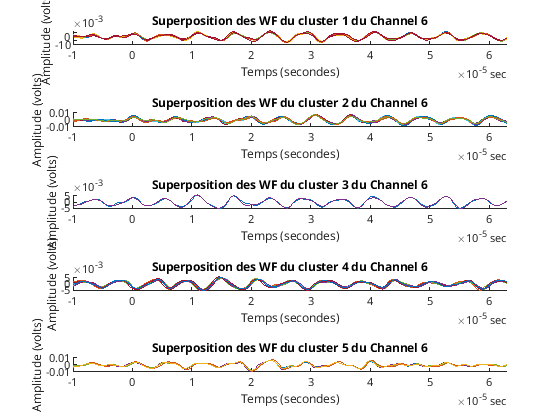

 ;
Ampl = true;
legen = false;
Affi = false;
fenetre1 = -10*1e-6;
fenetre2 = 63*1e-6;
Affiseuil = false;
thrdB =36;
fe = WF.Properties.SampleRate;
if Channel==1
    dt = dt1; 
elseif Channel==2
    dt = dt2; 
elseif Channel==3
    dt = dt3;
elseif Channel==4
    dt = dt4;
elseif Channel==5
    dt = dt5;
elseif Channel==6
    dt = dt6;
end


len1 = size(Multi);
tiledlayout(len1(2),1);
for i = 1:len1(2)
    nexttile
    hold on
    l = size(Multi{i});
    labels = {};
    for j = 1:l(2)
        if Ampl == 1
            G = (10^((HDD.AMP(HDD.HDDWF==strcat(string(Channel),'_',string(Multi{i}(1))))+40)/20)*1e-6)/(10^((HDD.AMP(HDD.HDDWF==strcat(string(Channel),'_',string(Multi{i}(j))))+40)/20)*1e-6);
            plot(WF.Time+dt(Multi{i}(1),Multi{i}(j))/fe,G.*WF.(strcat(string(Channel),'_',string(Multi{i}(j)))));            
        else
            plot(WF.Time+dt(Multi{i}(1),Multi{i}(j))/fe,WF.(strcat(string(Channel),'_',string(Multi{i}(j)))));
        end
        labels = [labels string(Multi{i}(j))];
    end
    if Affiseuil == 1
        thr = zeros(size(WF.Time))+10^((thrdB+40)/20)*1e-6;
        plot(WF.Time,thr,'b--');
        plot(WF.Time,-thr,'b--');
    end
    hold off
    xlabel({'Temps (secondes)'});
    ylabel({'Amplitude (volts)'});
    title(strcat("Superposition des WF du cluster ",string(i)," du Channel ",string(Channel)));
    if pretrig == 1
        if Affi == 1
            xlim(seconds([0 (impul-156)/(5e6)]));                                                
        else
            xlim(seconds([fenetre1 fenetre2]));
        end    
    else
        if Affi == 1
            xlim(seconds([-2e-05 (impul-156)/(5e6)]));                                                
        else
            xlim(seconds([fenetre1 fenetre2]));
        end
    end
    if legen == 1
        lgd = legend(labels,'Location','eastoutside','FontSize',5,'NumColumns',2);        
    end
end

## Décorrélation

 ;
if pretrig == 1
    init = 156;
else
    init = 1;
end
[Mulcor1,Mulcor2,Muldt1,Muldt2] = decorrelation(Multi,Multi2,WF,init,impul);

## Affichage matrices corrélation des clusters           

 ;
Num_multi = 3;
figure();
xvalues = Multi{Num_multi};
yvalues = Multi{Num_multi};
heatmap(xvalues,yvalues,Mulcor1{Num_multi});
colormap jet;
title(strcat("Corrélation WF channel 1 du cluster ",string(Num_multi)));
xlabel('Hits');
ylabel('Hits');
caxis([0.85 1]);
figure();
xvalues = Multi2{Num_multi};
yvalues = Multi2{Num_multi};
heatmap(xvalues,yvalues,Mulcor2{Num_multi});

colormap jet;
title(strcat("Corrélation WF channel 2 du cluster ",string(Num_multi)));
xlabel('Hits');
ylabel('Hits');
caxis([0.85 1]);

## Décorrélation par rapport à une WF et 2 à 2

 
Num_WF = 2;
capteur = 2;
if capteur == 1
    TwobyTwo = diag(Mulcor1{Num_multi},1);
    lineWF = [Mulcor1{Num_multi}(1:Num_WF,Num_WF)' Mulcor1{Num_multi}(Num_WF,(Num_WF+1):end)];
    figure();
    plot(Multi{Num_multi}(2:end),TwobyTwo,'g.','MarkerSize',25);
    hold on;
    plot(Multi{Num_multi},lineWF,'b.','MarkerSize',10);
    ylim([min([lineWF TwobyTwo']) 1]);
    hold off;
else 
    TwobyTwo = diag(Mulcor2{Num_multi},1);
    lineWF = [Mulcor2{Num_multi}(1:Num_WF,Num_WF)' Mulcor2{Num_multi}(Num_WF,(Num_WF+1):end)];
    figure();
    plot(Multi2{Num_multi}(2:end),TwobyTwo,'g.','MarkerSize',25);
    hold on;
    plot(Multi2{Num_multi},lineWF,'b.','MarkerSize',10);
    ylim([min([lineWF TwobyTwo']) 1]);
    hold off;
end
title(strcat("Corrélations entre WF au sein du cluster ",string(Num_WF)," du channel ",string(capteur)));
ylabel("Inter-corrélation normalisée");
xlabel("Numéro de WF");
legend({"WF corrélées 2 à 2",strcat("WF corrélées avec la WF n° ",string(Num_WF))},'Location','southwest');